# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

% RA = 2*5.5;    % ohm (2 motors)
% JA = 0.0008+0.00055; % motor inertia
% LA = 6.6e-3/2; % rotor inductor (2 motors)
% BA = 0.00000132+0.00000420;   % rotor friction
% Kemf = (0.00782+0.00819)/2; % motor constant
% Km = Kemf;
% % køretøj
% NG = 9.69; % gear
% WR = 0.03; % wheel radius
% Bw = 0.155; % wheel distance
% % model parts used in Simulink
% mmotor = 0.193;   % total mass of motor and gear [kg]
% mframe = 0.32;    % total mass of frame and base print [kg]
% mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
% mpdist =  0.10;   % distance to lit [m]
% % disturbance position (Z)
% pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf([1.1775 1.68],[1 7.334 7.141]) 

Gvu =
 
     1.177 s + 1.68
  ---------------------
  s^2 + 7.334 s + 7.141
 
Continuous-time transfer function.
Model Properties


## Bodeplot

pole(Gvu)

ans =    -6.1782
   -1.1558


isstable(Gvu)

ans = logical
   1


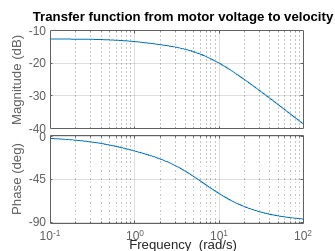

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

% % Design parameters
% N_i = 4%N_i_vu;
% gamma_m = 100%gamma_vu;
% 
% phi_i = rad2deg(-atan(1/N_i));
% phi_G = -180+gamma_m-phi_i;
% 
% bode(Gvu)
% 
% [mag,phase,wout] = bode(Gvu);
% omega_c = interp1(squeeze(phase),wout,phi_G);
% tau_i = N_i/omega_c;
% C_i = tf([tau_i 1],[tau_i 0]);
% Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
% G_vu_ol = Kp*C_i*Gvu;
% G_vu_cl = G_vu_ol/(1+G_vu_ol);
% bode(G_vu_ol)
% step(G_vu_cl)

N_i = 3;
t_r = 0.2;

omega_c = 2.2/t_r;
tau_i = N_i/omega_c

tau_i = 0.2727

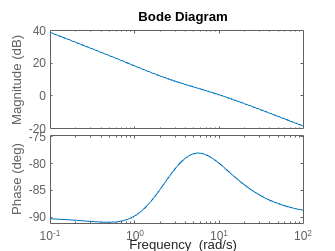

C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

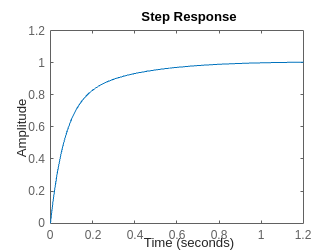

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 10.1357

t_i_vu = tau_i

t_i_vu = 0.2727

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -3.982e05 s^4 - 5.145e08 s^3 - 8.856e10 s^2 - 3.181e11 s - 9.517e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.943e08 s^4 + 9.515e09 s^3 - 4.737e09 s^2 - 7.052e11 s - 1.889e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


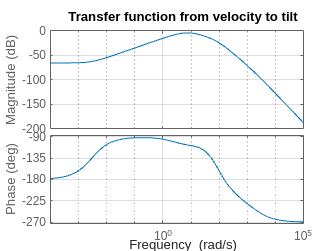

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5823

fpeak = 7.5490

tau_i = 1/fpeak

tau_i = 0.1325

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1325 s - 1
  -------------
    0.1325 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                5.274e04 s^5 + 6.855e07 s^4 + 1.225e10 s^3 + 1.307e11 s^2 + 3.182e11 s + 9.517e08
  -------------------------------------------------------------------------------------------------------------
  0.1325 s^8 + 320.4 s^7 + 1.744e05 s^6 + 2.574e07 s^5 + 1.26e09 s^4 - 6.275e08 s^3 - 9.342e10 s^2 - 2.502e11 s
 
Continuous-time transfer function.


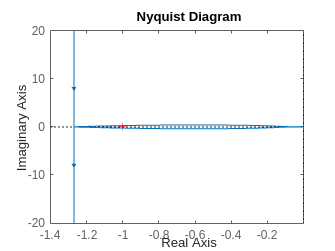

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 3.982e05 s^5 + 5.175e08 s^4 + 9.244e10 s^3 + 9.866e11 s^2 + 2.402e12 s + 7.185e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.947e08 s^5 + 1.003e10 s^4 + 8.77e10 s^3 + 2.814e11 s^2 + 5.13e11 s + 7.185e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1325

## Tilt to velocity controller PI-lead

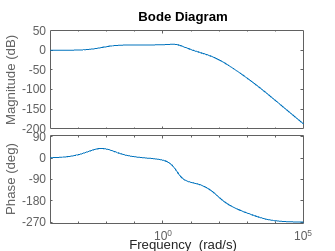

bode(G_post_cl)

% Design parameters
N_i =4%N_i_tv;

N_i = 4

gamma_m = 65%gamma_tv;

gamma_m = 65

alpha = 0.05%alpha_tv;

alpha = 0.0500



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.03959 s + 1
  -------------
    0.03959 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.04426 s + 1
  --------------
  0.002213 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
             2.969e07 s^7 + 4.001e10 s^6 + 8.756e12 s^5 + 4.254e14 s^4 + 7.632e15 s^3 + 5.055e16 s^2 + 1.022e17 s + 3.057e14
  -------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2870 s^9 + 2.409e06 s^8 + 7.896e08 s^7 + 9.801e10 s^6 + 4.621e12 s^5 + 3.991e13 s^4 + 1.276e14 s^3 + 2.318e14 s^2 + 3.246e12 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                 2.969e07 s^7 + 4.001e10 s^6 + 8.756e12 s^5 + 4.254e14 s^4 + 7.632e15 s^3 + 5.055e16 s^2 + 1.022e17 s + 3.057e14
  ----------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2870 s^9 + 2.409e06 s^8 + 8.193e08 s^7 + 1.38e11 s^6 + 1.338e13 s^5 + 4.653e14 s^4 + 7.76e15 s^3 + 5.078e16 s^2 + 1.022e17 s + 3.057e14
 
Continuous-time transfer function.


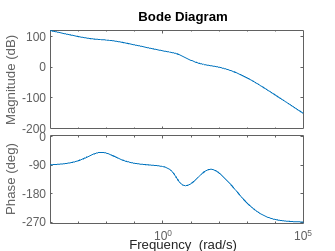


bode(G_tv_ol)

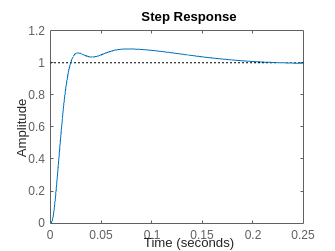

step(G_tv_cl)

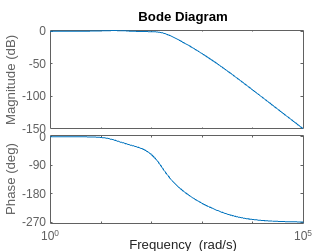

bode(G_tv_cl)

## Flush values to simulink

t_i_post

t_i_post = 0.1325

t_lead_tv = tau_D

t_lead_tv = 0.0443

t_i_tv = tau_i

t_i_tv = 0.0396

K_tv = Kp

K_tv = 3.7283

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                 -2.654e07 s^6 - 2.751e10 s^5 - 9.744e11 s^4 - 6.281e12 s^3 + 5.21e13 s^2 + 5.987e14 s + 1.343e15
  -------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2418 s^8 + 1.382e06 s^7 + 2.757e08 s^6 + 2.175e10 s^5 + 9.112e11 s^4 + 1.67e13 s^3 + 1.119e14 s^2 + 2.263e14 s + 6.766e11
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


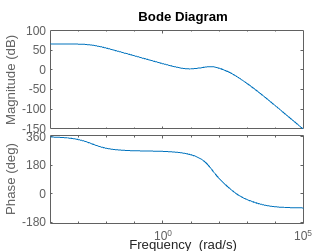

bode(G_vreft)



% Design parameters
N_i = 2.5%N_i_vreft;

N_i = 2.5000

gamma_m = 65+360%gamma_vreft;

gamma_m = 425

alpha = 0.75 %alpha_vreft;

alpha = 0.7500



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.5749 s + 1
  ------------
    0.5749 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.2656 s + 1
  ------------
  0.1992 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
            -1.688e07 s^8 - 1.759e10 s^7 - 7.163e11 s^6 - 7.523e12 s^5 + 7.09e12 s^4 + 5.371e14 s^3 + 3.168e15 s^2 + 7.197e15 s + 5.596e15
  ---------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2423 s^10 + 1.395e06 s^9 + 2.827e08 s^8 + 2.313e10 s^7 + 1.02e12 s^6 + 2.128e13 s^5 + 1.957e14 s^4 + 7.88e14 s^3 + 1.137e15 s^2 + 3.397e12 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                   -1.688e07 s^8 - 1.759e10 s^7 - 7.163e11 s^6 - 7.523e12 s^5 + 7.09e12 s^4 + 5.371e14 s^3 + 3.168e15 s^2 + 7.197e15 s + 5.596e15
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2423 s^10 + 1.395e06 s^9 + 2.658e08 s^8 + 5.541e09 s^7 + 3.041e11 s^6 + 1.376e13 s^5 + 2.028e14 s^4 + 1.325e15 s^3 + 4.305e15 s^2 + 7.201e15 s + 5.596e15
 
Continuous-time transfer function.


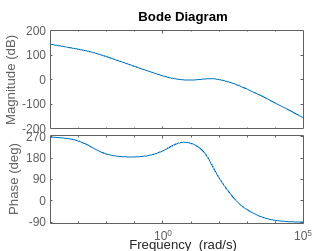


bode(G_vreft_ol)

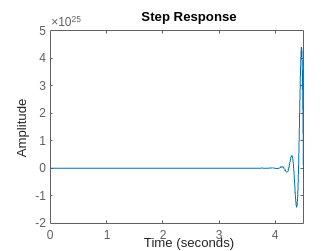

step(G_vreft_cl)

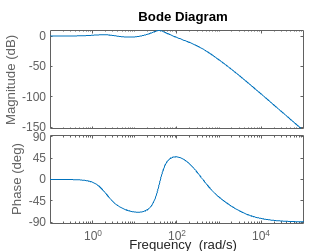

bode(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 0.5749

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.2656    1.0000


den_lead_vreft =     0.1992    1.0000


K_vreft = Kp

K_vreft = 0.4771

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
             -6.332e04 s^9 - 7.864e07 s^8 - 1.589e10 s^7 - 5.666e11 s^6 - 5.602e12 s^5 + 8.829e12 s^4 + 4.276e14 s^3 + 2.333e15 s^2 + 4.419e15 s + 1.85e15
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2423 s^11 + 1.395e06 s^10 + 2.729e08 s^9 + 1.274e10 s^8 + 3.86e11 s^7 + 1.417e13 s^6 + 2.057e14 s^5 + 1.295e15 s^4 + 3.716e15 s^3 + 4.536e15 s^2 + 1.85e15 s
 
Continuous-time transfer function.


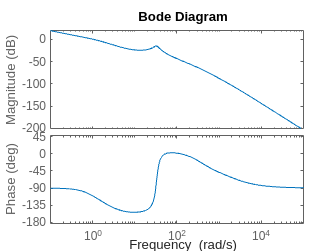

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.6919 + 0.0000i
  -0.3393 + 0.0665i
  -0.3393 - 0.0665i
  -0.0421 + 0.0000i
   0.0042 + 0.0325i
   0.0042 - 0.0325i
  -0.0074 + 0.0000i
  -0.0058 + 0.0000i
  -0.0036 + 0.0000i




% Design parameters
gamma_m = 65+360%gamma_xvref;

gamma_m = 425

alpha = 0.8%alpha_xvref;

alpha = 0.8000


phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  NaN
 
Static gain.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);

Error using DynamicSystem/bode (line 69)
The frequency grid must be specified as a vector of real numbers.

Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)
G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

bode(G_xvref_ol)
step(G_xvref_cl)
bode(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v')
K_xvref = Kp

## X step test

x_test = 1;
x_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

x_test = 0;
v_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 10.1357

t_i_vu

t_i_vu = 0.2727

K_post

K_post = -1

t_i_post

t_i_post = 0.1325

t_lead_tv

t_lead_tv = 0.0443

t_i_tv

t_i_tv = 0.0396

K_tv

K_tv = 3.7283

t_i_vreft

t_i_vreft = 0.5749

num_lead_vreft

num_lead_vreft =     0.2656    1.0000


den_lead_vreft

den_lead_vreft =     0.1992    1.0000


K_vreft

K_vreft = 0.4771

K_xvref

K_xvref = 1

num_lead_xvref

num_lead_xvref = 0

den_lead_xvref

den_lead_xvref = 1